# Make plots after RND filtering

clear

## import the data if already converted to ANA

dir = 'E:\PhD\Adamantane_data\data\ascii_conv_data\Ada_PEPICO_hv350eV_ke260_0003_ascii\Ada_PEPICO_hv350eV_ke260_0003_ana';

% dir= 'E:\PhD\Adamantane_data\data\ascii_conv_data\Ada_PEPICO_hv287p61eV_ke260_0001_ascii\Ada_PEPICO_hv287p61eV_ke260_0001_ana';
raw_data = IO.import_raw(dir);
mdata = IO.import_metadata(dir);
data            = macro.filter(raw_data, mdata); %define the multiplicity of events
data_corrected = macro.correct(data, mdata);

Log: Detector image translation correction performed on det1
Log: Detector image rotation correction performed on det1
Log: Radial angle-dependent correction performed on det1
Log: Detector image translation correction performed on det2
Log: Detector image rotation correction performed on det2
Log: delta TOF correction performed on det2


data_converted = macro.convert(data_corrected, mdata);

Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2


%Generate RND events
% raw_data = generate_rnd(data,raw_data)

## Get data stats

[data_stats] =get_data_stats(data_converted);

The Scaling factor is 0.51938


## TOF and M2Q spectra All ions

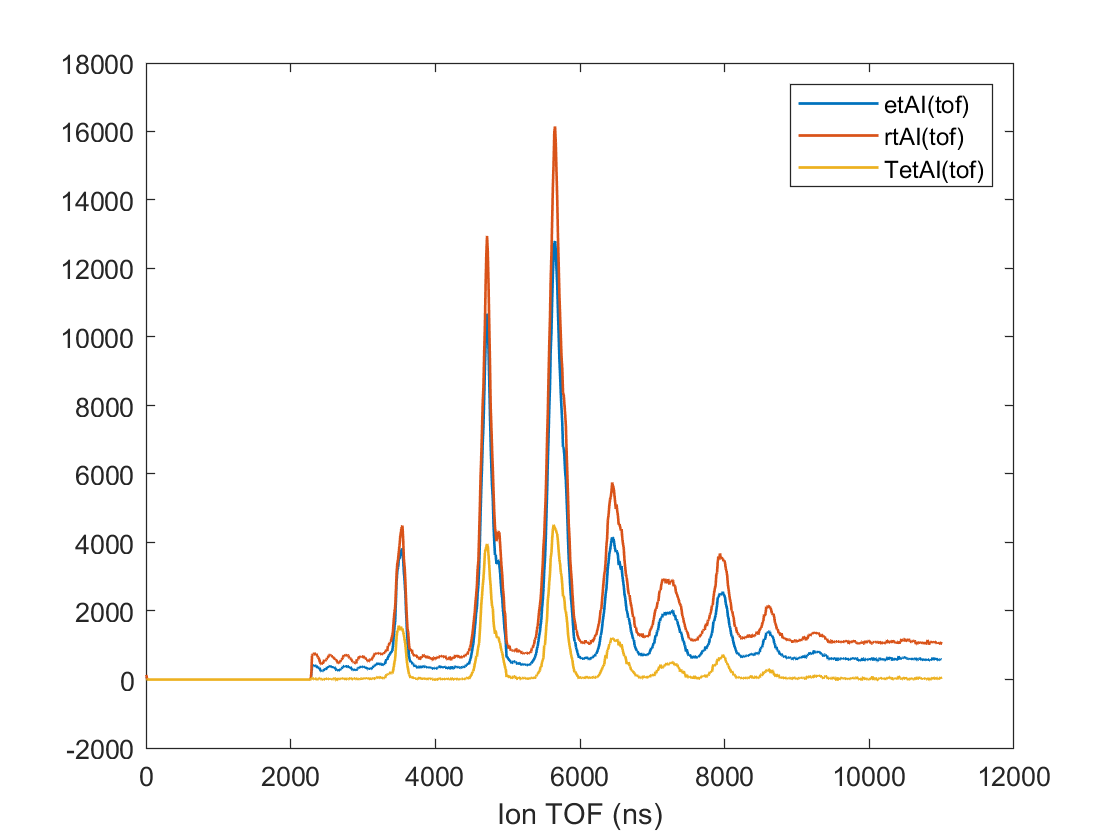

[Tet_tof,Tet_tof_error] = plot_ion_tof(data_converted, data_stats);

% [Tet_m2q,Tet_tof_m2q] = plot_ion_m2q(data_converted, data_stats);

## ION KE

figure
[Tet_ke,Tet_ke_error] = plot_ion_ker(data_converted, data_stats,'manual_selection');

Undefined function or variable 'plot_ion_ker'.

figure
[Tet_ke,Tet_ke_error] = plot_ion_ker(data_converted, data_stats,'m2q_label');

## PIPICO

[Tet_tof2] = plot_pipico(data_converted, data_stats);
% [Tet_m2q2] = plot_pipico_m2q(data_converted, data_stats,mdata);
% xlim([10 70])
% ylim([10 100])
% axis square
% caxis([0 30])

## PEPICO


tof_range =[2000 ; 11000];
% tof_range =[4500 ; 5000];

 [TetEI_x_tof,Xedges,Yedges] = plot_pepico(data_converted, data_stats,tof_range);

m2q_l = mdata.conv.det2.m2q_label.labels ;
% [TetEI_x_m2q,Xedges,Yedges] = plot_pepico_m2q(data_converted, data_stats,m2q_l(14));

% for ii = 1:length(mdata.conv.det2.m2q_label.labels)
%     m2q_l =mdata.conv.det2.m2q_label.labels(ii);
%     [TetEI_x_m2q,Xedges,Yedges] = plot_pepico_m2q(data_converted, data_stats,m2q_l);
%     C_n =min(fix(m2q_l/12),10);
%     label =strcat('C_',num2str(C_n),'H_',num2str(m2q_l-C_n*12),'^+');
%     title(label)
% end

## Select the ion pair

m2q_1 = 12*2+1*5; m2q_2 = 12*8+1*11;
Center(1) = convert.m2q_2_TOF(m2q_1,mdata.conv.det2.m2q.factor,mdata.conv.det2.m2q.t0)

Center = 4.8804e+03

Center(2) = convert.m2q_2_TOF(m2q_2,mdata.conv.det2.m2q.factor,mdata.conv.det2.m2q.t0)

Center = 	1.0e+03 *

    4.8804    9.3222


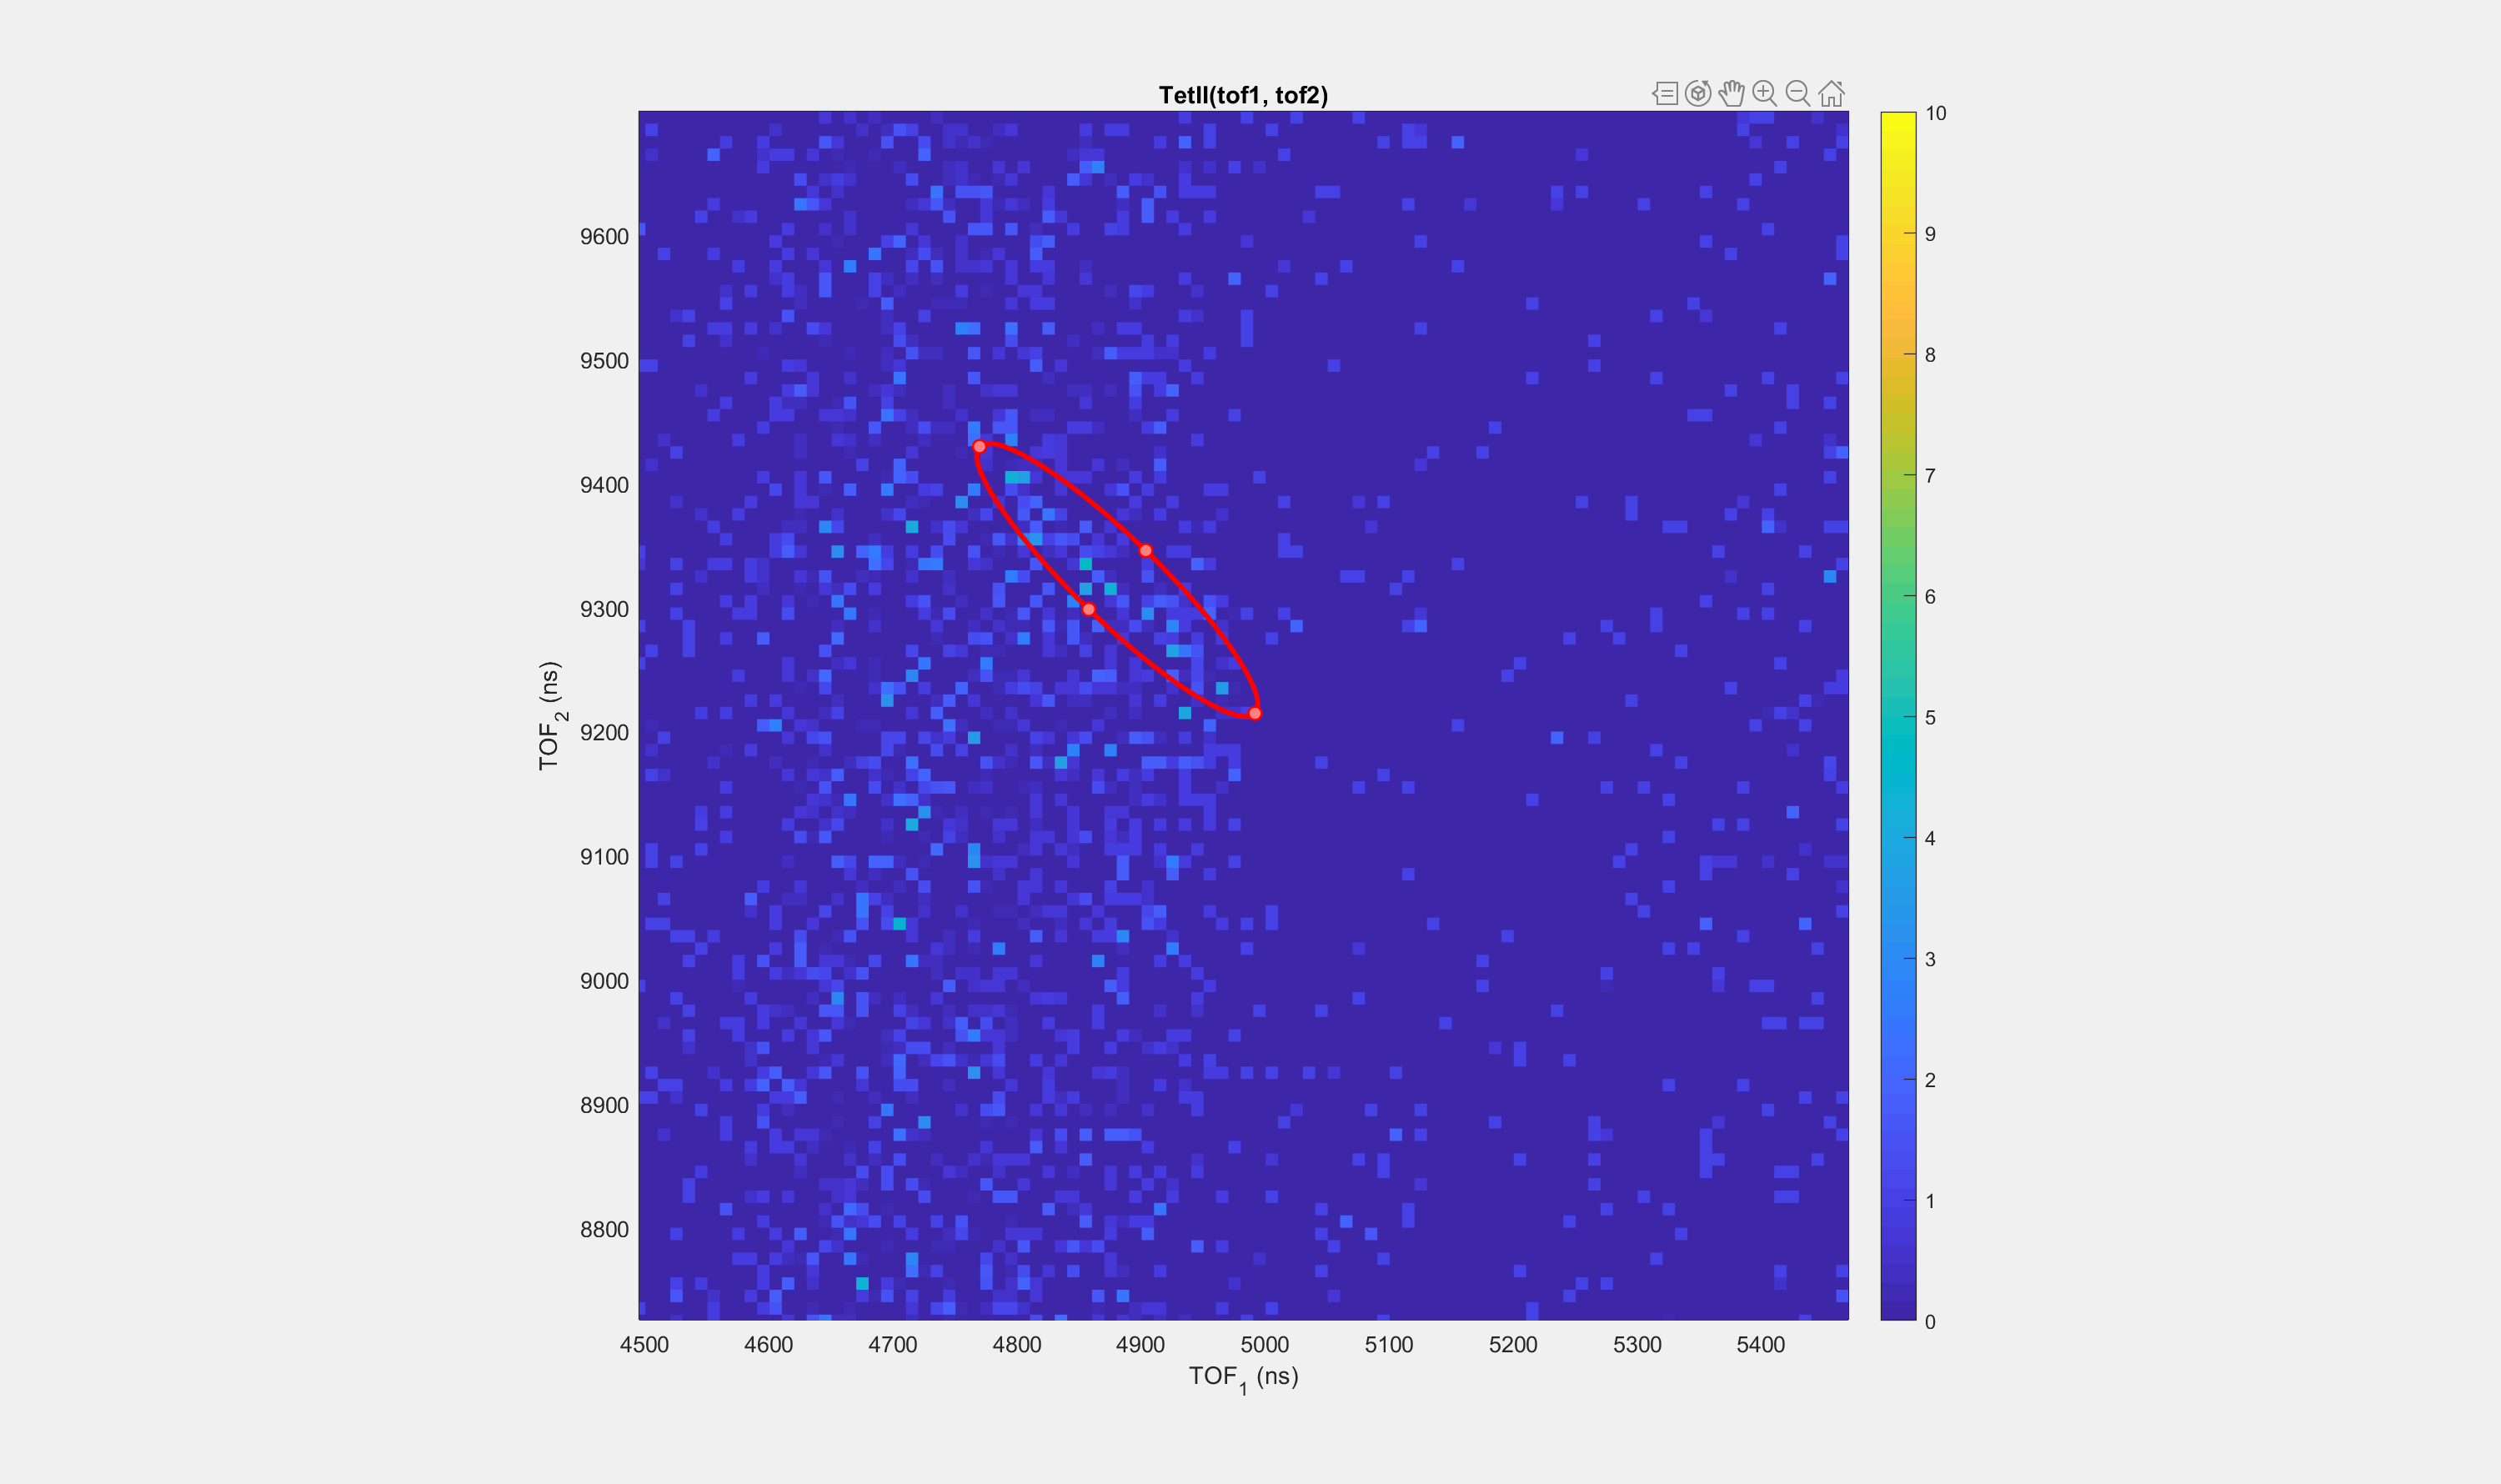

roi updated



[roi] = get_roi_pipico(data_converted, data_stats,Center);%%

## Ion pair specific Electron Spectra

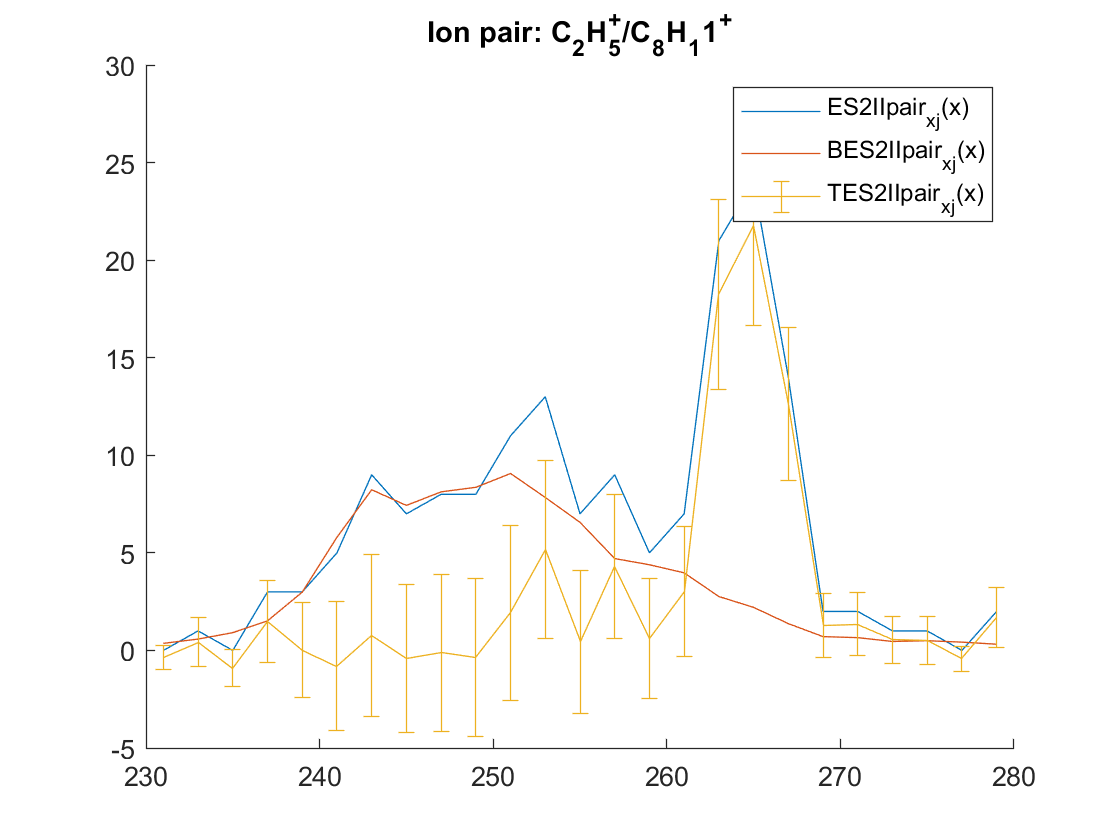


tof_1 =[roi.Center(1)-500 ; roi.Center(1)+500];
tof_2 =[roi.Center(2)-500 ; roi.Center(2)+500];
mdata = md_all(); 
% macro.plot(data_converted, mdata)
TES2IIpair_x = plot_ES_ion_pair2(data_converted, data_stats,roi,tof_1,tof_2);
%% give name
m2q1 = round(convert.TOF_2_m2q(roi.Center(1),mdata.conv.det2.m2q.factor,mdata.conv.det2.m2q.t0));
m2q2 = round(convert.TOF_2_m2q(roi.Center(2),mdata.conv.det2.m2q.factor,mdata.conv.det2.m2q.t0));
C_n1 =min(fix(m2q1/12),10);
label1 =strcat('C_',num2str(C_n1),'H_',num2str(m2q1-C_n1*12),'^+');
C_n2 =min(fix(m2q2/12),10);
label2 =strcat('C_',num2str(C_n2),'H_',num2str(m2q2-C_n2*12),'^+');
title(['Ion pair: ', label1,'/',label2])

## Slices of PEPICO

% for jj=1:7;
tof_range =[2000 ; 11000];
% tof_range =[4500 ; 5000];
%(11); %hAxes(1) =subplot(1,3,1); hAxes(2) =subplot(1,3,2);hAxes(3)  =subplot(1,3,3);
for i=1:3
%     subplot(1,3,i)
figure
%       plot_pepico(data_converted(i), data_stats(i),tof_range);
%     title([num2str(hv(i)), ' eV'])
%     AES_1 = sum(TetEI_x_tof,2);
%     plot(Xcenters,AES_1)


C1=8; H1=9; H2=10; H3 =12;
m2q_1 = 12*C1+1*H1; m2q_2 = 12*C1+1*H2;  m2q_3 = 12*C1+1*H3; 
label1 =sprintf('C_%dH_{%d}^+', C1,H1);label2 =sprintf('C_%dH_{%d}^+', C1,H2); label3 =sprintf('C_%dH_{%d}^+', C1,H3);
tof1 = convert.m2q_2_TOF(m2q_1,mdata.conv.det2.m2q.factor,mdata.conv.det2.m2q.t0);
tof2 = convert.m2q_2_TOF(m2q_2,mdata.conv.det2.m2q.factor,mdata.conv.det2.m2q.t0);
tof3 = convert.m2q_2_TOF(m2q_3,mdata.conv.det2.m2q.factor,mdata.conv.det2.m2q.t0);
[TetEI_x_tof,Xcenters,Ycenters] = plot_pepico(data_converted1, data_stats1,[tof2-50;tof2+50 ]);

tof_centers = Ycenters;%Yedges(1:end-1) + diff(Yedges) / 2; %tof values
energy_val = Xcenters;%Xedges(1:end-1) + diff(Xedges) / 2;
id1 = tof_centers > tof1-50 & tof_centers < tof1+50;
id2 = tof_centers > tof2-50 & tof_centers < tof2+50;
id3 = tof_centers > tof3-50 & tof_centers < tof3+50;
 figure;
%  for i=1:3
%     subplot(3,1,i); 
    y1 =sum(TetEI_x_tof(:,id1), 2);
    y2 =sum(TetEI_x_tof(:,id2), 2);
    y3 =sum(TetEI_x_tof(:,id3), 2);
    plot(energy_val,y1./max(y1),'DisplayName',label1,'LineWidth', 2); hold on
    plot(energy_val,y2./max(y2),'DisplayName',label2,'LineWidth', 2); hold on
    plot(energy_val,y3./max(y3),'DisplayName',label3,'LineWidth', 2);  
    ylim([0 1])
%      plot(energy_val,y1,'DisplayName',label1,'LineWidth', 2); hold on
%      plot(energy_val,y2,'DisplayName',label2,'LineWidth', 2); hold on
%     plot(energy_val,y3,'DisplayName',label3,'LineWidth', 2);  
    
    legend 
    title([num2str(hv(i)), ' eV'])
    
end
%  